# Hormigón EHE-08

## Ejemplo 3

Este ejemplo consiste en la creación de una sección de hormigón armado y pretensado, en el cálculo de solicitaciones a partir de una pareja de deformaciones y en el cálculo de la pareja de deformaciones en función de las solicitaciones. Al final, se calcula el máximo momento flector para una directa dada. Se recomiendan leer y replicar previamente el [ejemplo 1](https://htmlpreview.github.io/?https://github.com/quelopelo/hormigon-ehe08/blob/main/docs/ejemplo1.html) y el [ejemplo 2](https://htmlpreview.github.io/?https://github.com/quelopelo/hormigon-ehe08/blob/main/docs/ejemplo2.html).

### Ingresar la sección de hormigón

En este ejemplo se trabaja con una sección tipo I de hormigón armado y pretensado.

En primer lugar, se definen los parámetros de los materiales y de la geometría de la sección a generar.

clear
run('..\init')

% Materiales
fck = 35;                   % Resistencia característica a compresión del hormigón (MPa)
fyk = 500;                  % Límite elástico característico del acero pasivo (MPa)
fpk = 1600;                 % Límite elástico característico del acero activo (MPa)
fp = 0.8 * 1200;            % Tensión inicial (con pérdidas) de pretensado en cada barra (MPa)
Ep = 190e3;                 % Módulo de elasticidad del acero pasivo (MPa)

% Geometría del hormigón
b_ala1 = 200;               % Ancho del ala inferior (mm)
b_ala2 = 400;               % Ancho del ala superior (mm)
b_alma = 100;               % Ancho de alma (mm)
h_total = 700;              % Altura tota (mm)
h_ala1 = 100;               % Altura del ala inferior (mm)
hp_ala1 = 50;               % Altura de la zona inclinada de ala inferior (mm)
h_ala2 = 200;               % Altura del ala superior (mm)
hp_ala2 = 50;               % Altura de la zona inclinada de ala superior (mm)

% Geometría del acero
rm1 = 28;                   % Recubrimiento mecánico de la armadura pasiva inferior (mm)
rm2 = 28;                   % Recubrimiento mecánico de la armadura pasiva superior (mm)
As1 = 5 * pi * (16/2)^2;    % Área de acero pasivo inferior, correspondiente a 5 Φ16 mm (mm2)
As2 = 5 * pi * (16/2)^2;    % Área de acero pasivo superior, correspondiente a 5 Φ16 mm (mm2)
rmp = [59, 73];             % Recubrimiento mecánico de la armadura activa despuesta en dos filas (mm)
np = [4, 3];                % Cantidad de cables de acero activo por cada fila
Api = 140;                  % Área de acero pretensado inferior de cada fila, correspondiente a 4 cables de 140 mm2 (mm2)

En segundo lugar, se generan las matrices 'geoHorm', 'geoAcPas' y 'geoAcAct' que contienen las propiedades geométricas del hormigón, del acero pasivo y del acero activo. Luego, se crea la sección mediante la función **crear_seccion**. La ayuda de esta función contiene información adicional de cómo se deben generar las matrices 'geoHorm', 'geoAcPas' y 'geoAcAct', así como de otros parámetros que pueden añadirse.

yVec = [0; h_ala1; h_ala1+hp_ala1; h_total-h_ala2-hp_ala2; h_total-hp_ala2; h_total];
bVec = [b_ala1; b_ala1; b_alma; b_alma; b_ala2; b_ala2];

geoHorm = [yVec, bVec];                     % Matriz de geometría del hormigón
geoAcPas = [rm1, As1; h_total-rm2, As2];    % Matriz de geometría de acero pasivo
geoAcAct = [rmp(1), np(1)*Api, fp; 
            rmp(2), np(2)*Api, fp];         % Matriz de geometría de acero activo

S = crear_seccion(geoHorm, fck, [], geoAcPas, fyk, [], geoAcAct, fpk, Ep);

El estructurado 'S' contiene la información ingresada y otras propiedades calculadas, que dependen únicamente de la sección (y no de las solicitaciones actuantes). En lo que queda de este ejemplo se trabaja con la sección generada.

### Calcular solicitaciones para una pareja de deformaciones

En esta sección se calculan las solicitaciones para una pareja de deformaciones dada meidante la función **solicitaciones_normales**. Opcionalmente, esta función permite la introducción de una bandera booleana de modo que se considere la resistencia a flexotracción del hormigón.

eInf = 0;
eSup = 0;

[N, M] = solicitaciones_normales(eInf, eSup, S);
fprintf("Solicitaciones para la pareja de deformaciones [eInf, eSup] = [%.5f, %.5f]\nDirecta: %.0f kN\nMomento flector: %.0f kN.m", eInf, eSup, N/1e3, M/1e6);

Solicitaciones para la pareja de deformaciones [eInf, eSup] = [0.00000, 0.00000]
Directa: 941 kN
Momento flector: -310 kN.m

Nótese que al imponer una pareja de deformaciones nulas se obtienen una directa y un momento flector contrarios a los que ejerce el pretensado considerado como fuerza externa.

### Calcular deformaciones para una pareja de solicitaciones

El programa también permite obtener las deformaciones para una pareja de solicitaciones. En esta sección se calculan las deformaciones unitarias de las fibras inferior y superior del hormigón para una directa constante nula y para un momento flector variable.

En primer lugar, se generan los vectores de momentos flectores ('MVec') y los contenedores para albergar las deformaciones unitarias de las fibras inferior y superior ('eInfVec' y 'eInfSup'). Luego, se utiliza la función **deformaciones_normales** para completar estos últimos vectores.

MVec = linspace(S.MMin, S.MMax, 200);       % Vector de momentos flectores (N.mm)
eInfVec = zeros(size(MVec));                % Vector de deformaciones unitarias de la fibra inferior
eSupVec = zeros(size(MVec));                % Vector de deformaciones unitarias de la fibra superior

for i = 1 : length(MVec)
    [eInfVec(i), eSupVec(i)] = deformaciones_normales(0, MVec(i), S);
end

En segundo lugar, se realiza el gráfico. Obsérvese que el código es relativamente extenso para mejorar la presentación del diagrama de interacción, pero podría reducirse solamente a la última línea.

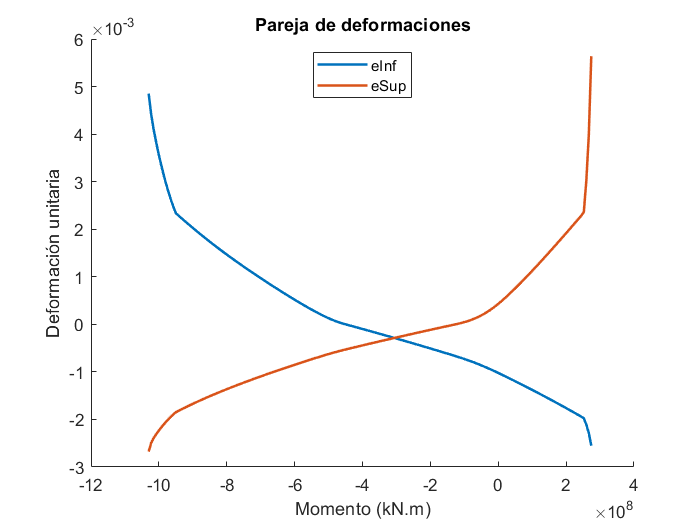

figure
title("Pareja de deformaciones")
xlabel("Momento (kN.m)")
ylabel("Deformación unitaria")

hold on
plot(MVec, eInfVec, "LineWidth", 1.5, "DisplayName", "eInf")
plot(MVec, eSupVec, "LineWidth", 1.5, "DisplayName", "eSup")
legend("Location", "north")

### Verificar la sección para una pareja de solicitaciones

En esta última sección se determinan los momentos flectores máximos (en los dos sentidos) para una directa dada.

Para ello se debe utilizar la función **coeficiente_solicitaciones_normales**, que devuelve el factor de utilización de la sección de hormigón armado y pretensado para unas directa y momento flector dados.

N = -2e6;                           % Directa dada (N)
coefVec = zeros(size(MVec));        % Vector de coeficientes o factores de utilización

for i = 1 : length(MVec)
    coefVec(i) = coeficiente_solicitaciones_normales(N, MVec(i), S);
end

Luego, se realiza el gráfico. Obsérvese que el código es relativamente extenso para mejorar la presentación del diagrama de interacción, pero podría reducirse a una única línea.

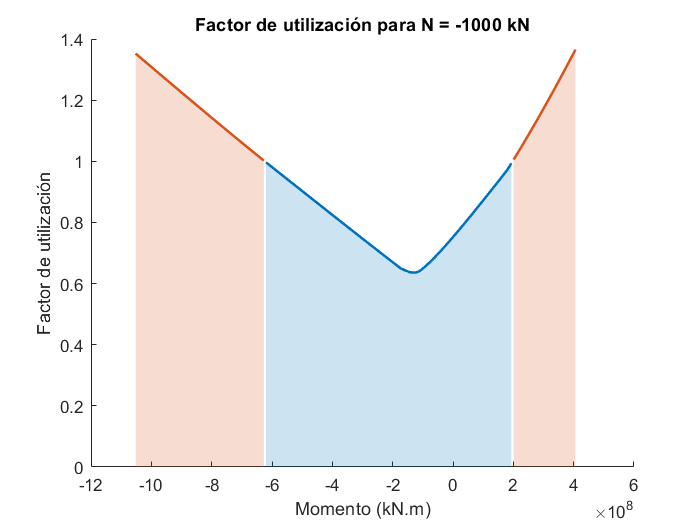

[~, indMin] = min(coefVec);
ind1 = and(coefVec > 1, MVec <= MVec(indMin));
ind2 = coefVec <= 1;
ind3 = and(coefVec > 1, MVec >= MVec(indMin));

figure
title("Factor de utilización para N = -1000 kN")
xlabel("Momento (kN.m)")
ylabel("Factor de utilización")

hold on
area(MVec(ind1), coefVec(ind1), "LineStyle", "none", "FaceColor", "#D95319", "FaceAlpha", 0.2)
area(MVec(ind2), coefVec(ind2), "LineStyle", "none", "FaceColor", "#0072BD", "FaceAlpha", 0.2)
area(MVec(ind3), coefVec(ind3), "LineStyle", "none", "FaceColor", "#D95319", "FaceAlpha", 0.2)
plot(MVec(ind1), coefVec(ind1), "Color", "#D95319", "LineWidth", 1.5)
plot(MVec(ind2), coefVec(ind2), "Color", "#0072BD", "LineWidth", 1.5)
plot(MVec(ind3), coefVec(ind3), "Color", "#D95319", "LineWidth", 1.5)

Por último, si se desea obtener el momento flector cuando se tracciona la fibra inferior se puede resolver mediante un problema de optimización.

problem.objective = @(x) coeficiente_solicitaciones_normales(N, x, S) - 1;
problem.x0 = [S.MMin, 0];
problem.solver = 'fzero';
problem.options = optimset('Display', 'off');

MMax = fzero(problem);
fprintf("El máximo momento flector (en valor absoluto) para N = %.0f kN es %.0f kN.m", N/1e3, abs(MMax/1e6))

El máximo momento flector para N = -2000 kN es 624 kN.m

A partir de un problema de optimización correctamente definido, y mediante el uso de la función **coeficiente_solicitaciones_normales**, también es posible dimensionar una sección de hormigón armado y/o pretensado.